**PART 1**

Question 1

% store exact value of 
% area of the parabolic 
% segment
a = 1

a = 1

r = 1/4

r = 0.2500

area_analytical = a/(1-r)

area_analytical = 1.3333

Question 2

% calculate first 20 partial
% sums
range = 1:20

range =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20


ps_b = (1/4).^(range-1)

ps_b =     1.0000    0.2500    0.0625    0.0156    0.0039    0.0010    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


ps_b = cumsum(ps_b)

ps_b =     1.0000    1.2500    1.3125    1.3281    1.3320    1.3330    1.3333    1.3333    1.3333    1.3333    1.3333    1.3333    1.3333    1.3333    1.3333    1.3333    1.3333    1.3333    1.3333    1.3333



ps_a = zeros(1, 20)

ps_a =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


s = 0

s = 0

for c = 1:20
    s = s + (1/4).^(c-1);
    ps_a(c) = s;
end
ps_a

ps_a =     1.0000    1.2500    1.3125    1.3281    1.3320    1.3330    1.3333    1.3333    1.3333    1.3333    1.3333    1.3333    1.3333    1.3333    1.3333    1.3333    1.3333    1.3333    1.3333    1.3333


Questions 3, 4a, 5

% plot partial sums as 
% distinct points
plot(range, ps_b, ".")
hold on
l = area_analytical + zeros(20, 1)

l =     1.3333
    1.3333
    1.3333
    1.3333
    1.3333
    1.3333
    1.3333
    1.3333
    1.3333
    1.3333


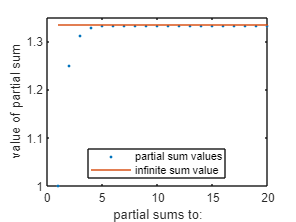

plot(l)
hold off
xlabel("partial sums to:")
ylabel("value of partial sum")
legend("partial sum values", "infinite sum value", 'Location', "south")

Question 4b

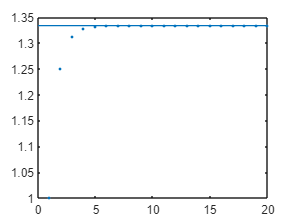

% same plot as before
plot(range, ps_b, ".")
hold on
line([0, 20], [area_analytical, area_analytical])
hold off

**PART 2**

Questions 1, 2, 3, 4

soln_analytical = 14/3

soln_analytical = 4.6667

a = 0

a = 0

b = 3

b = 3

n = 10

n = 10

deltax = (b-a)/n

deltax = 0.3000

Question 5

loc = a:deltax:b-deltax

loc =          0    0.3000    0.6000    0.9000    1.2000    1.5000    1.8000    2.1000    2.4000    2.7000


func = sqrt(loc+1)

func =     1.0000    1.1402    1.2649    1.3784    1.4832    1.5811    1.6733    1.7607    1.8439    1.9235


L10_n = cumsum(deltax.*func)

L10_n =     0.3000    0.6421    1.0215    1.4350    1.8800    2.3544    2.8564    3.3846    3.9377    4.5148


L10 = L10_n(end)

L10 = 4.5148

Question 6

loc = a+deltax:deltax:b

loc =     0.3000    0.6000    0.9000    1.2000    1.5000    1.8000    2.1000    2.4000    2.7000    3.0000


func = sqrt(loc+1)

func =     1.1402    1.2649    1.3784    1.4832    1.5811    1.6733    1.7607    1.8439    1.9235    2.0000


R10_n = cumsum(deltax.*func)

R10_n =     0.3421    0.7215    1.1350    1.5800    2.0544    2.5564    3.0846    3.6377    4.2148    4.8148


R10 = R10_n(end)

R10 = 4.8148

Question 7a, do 7b later!

n = 10:100

n =     10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59


deltax = (b-a)./n

deltax =     0.3000    0.2727    0.2500    0.2308    0.2143    0.2000    0.1875    0.1765    0.1667    0.1579    0.1500    0.1429    0.1364    0.1304    0.1250    0.1200    0.1154    0.1111    0.1071    0.1034    0.1000    0.0968    0.0938    0.0909    0.0882    0.0857    0.0833    0.0811    0.0789    0.0769    0.0750    0.0732    0.0714    0.0698    0.0682    0.0667    0.0652    0.0638    0.0625    0.0612    0.0600    0.0588    0.0577    0.0566    0.0556    0.0545    0.0536    0.0526    0.0517    0.0508


Ln = zeros(size(n))

Ln =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Rn = zeros(size(n))

Rn =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for i = n-9

    % left side
    loc = a:deltax(i):b-deltax(i);
    func = sqrt(loc+1);
    Lall = cumsum(deltax(i).*func);
    Ln(i) = Lall(end);

    % right side
    loc = a+deltax(i):deltax(i):b;
    func = sqrt(loc+1);
    Rall = cumsum(deltax(i).*func);
    Rn(i) = Rall(end);

end
Ln

Ln =     4.5148    4.5288    4.5404    4.5502    4.5586    4.5658    4.5722    4.5778    4.5828    4.5872    4.5912    4.5948    4.5981    4.6011    4.6038    4.6064    4.6087    4.6109    4.6129    4.6147    4.6165    4.6181    4.6196    4.6210    4.6224    4.6237    4.6249    4.6260    4.6271    4.6281    4.6290    4.6300    4.6308    4.6317    4.6325    4.6332    4.6340    4.6347    4.6353    4.6360    4.6366    4.6372    4.6378    4.6383    4.6388    4.6393    4.6398    4.6403    4.6407    4.6412


Rn

Rn =     4.8148    4.8015    4.7904    4.7809    4.7729    4.7658    4.7597    4.7543    4.7494    4.7451    4.7412    4.7377    4.7345    4.7315    4.7288    4.7264    4.7241    4.7220    4.7200    4.7182    4.7165    4.7149    4.7134    4.7119    4.7106    4.7094    4.7082    4.7071    4.7060    4.7050    4.7040    4.7031    4.7023    4.7014    4.7007    4.6999    4.6992    4.6985    4.6978    4.6972    4.6966    4.6960    4.6954    4.6949    4.6944    4.6939    4.6934    4.6929    4.6925    4.6920


Question 8

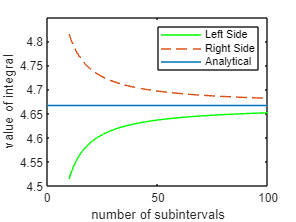

plot(n, Ln, "g")
hold on
plot(n, Rn, "--")
line([0, 100], [soln_analytical, soln_analytical])
hold off
legend("Left Side", "Right Side", "Analytical")
xlabel("number of subintervals")
ylabel("value of integral")